# Demo 6 - DE Analysis and Marker Gene Identification Functions

## Load example data set, X

cdgea; % set working directory
load example_data/markergeneident_demo X genelist s_tsne
% s_tsne is precomputed tSNE embedding

## Automatically cluster cells and explore cell type

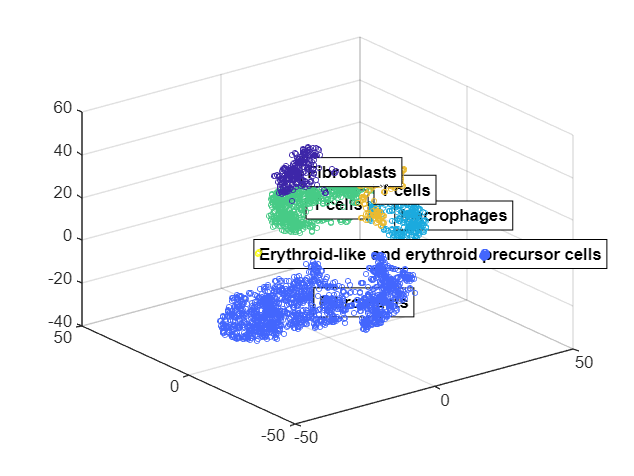

figure;
gui.sc_celltypeexplorer_auto(X, genelist, s_tsne, "species", "mouse");

## Show result of manually brushing cells and exploring cell type

To generate the figure: (1) run gui.sc_celltypeexplorer(X,genelist,s_tsne,"species","mouse") (2) brush and select cell cluster

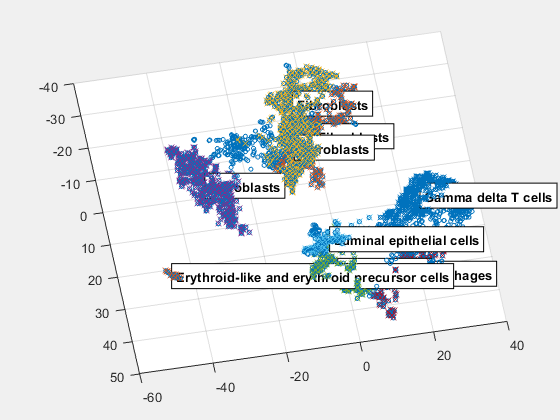

openfig('example_data/markergeneident_demo.fig');

## Group cells into clusters (k=6)

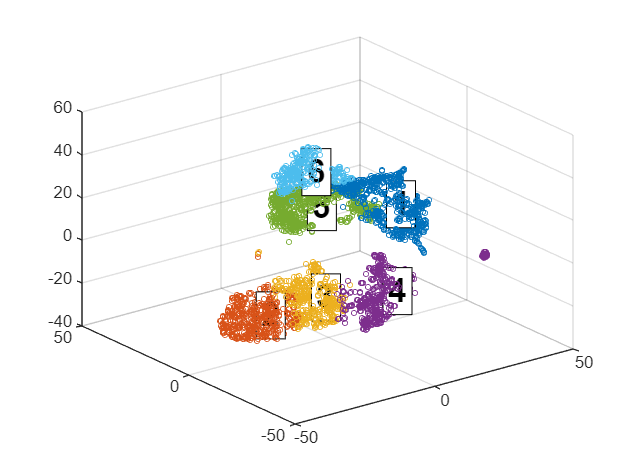

figure;
rng(1234)
cluster_kmedoids=sc_cluster_s(s_tsne, 6, 'type', 'kmedoids', 'plotit', true);

## Identify marker genes for cluster #4 against other clusters

gmarkers = sc_pickmarkers(X, genelist, cluster_kmedoids, 9);
gmarkers = gmarkers{4};

## Show expression level of top 9 marker genes

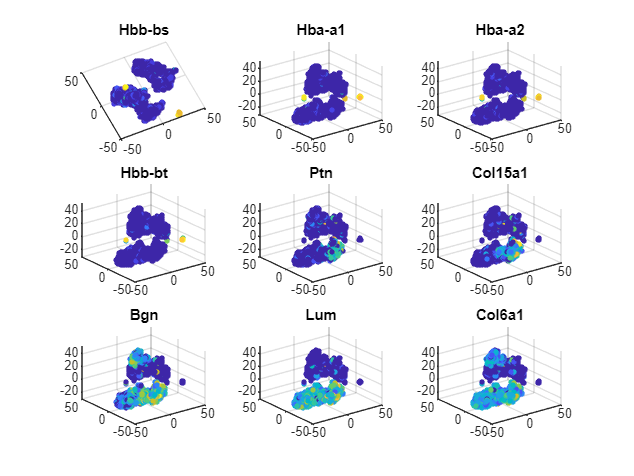

figure;
for k=1:9
    g = gmarkers(k);
    subplot(3,3,k)
    grp = log1p(X(genelist==g,:));
    scatter3(s_tsne(:,1), s_tsne(:,2), s_tsne(:,3), 10, grp, 'filled');
    title(g)
end
subplot(3, 3, 1)
view([-25 90])

## Show expression level of the top marker gene

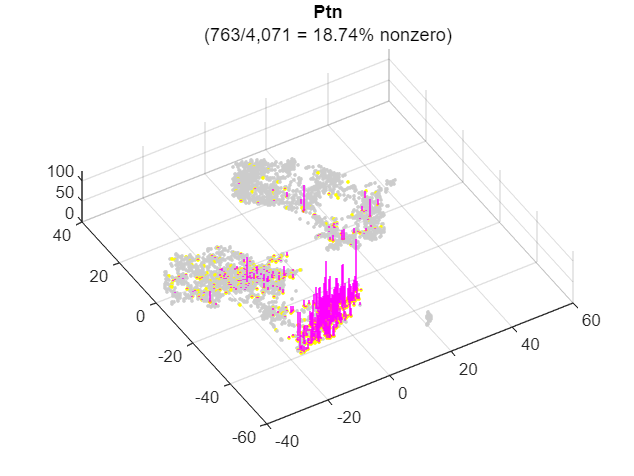

figure;
g = gmarkers(5);
sc_scattermarker(X, genelist, s_tsne, g);
% sc_stemscatter(s_tsne(:,1), s_tsne(:,2), log1p(X(genelist==g,:)));
title(g)
view([-31.03 77.60])

## Determine cell type for each cluster using marker genes (collected by PanglaoDB)

Tct = run.ml_alona(X, genelist, cluster_kmedoids, 'species', 'mouse')

Tct = 1×12 table
    C1_Cell_Type    C1_CTA_Score    C2_Cell_Type     C2_CTA_Score    C3_Cell_Type     C3_CTA_Score    C4_Cell_Type     C4_CTA_Score    C5_Cell_Type    C5_CTA_Score    C6_Cell_Type     C6_CTA_Score
    ____________    ____________    _____________    ____________    _____________    ____________    _____________    ____________    ____________    ____________    _____________    ____________

     "T cells"         12.964       "Fibroblasts"       46.347       "Fibroblasts"       46.602       "Fibroblasts"       40.616        "T cells"         24.513       "Fibroblasts"

## Another demo with example data of mouse pancreatic islet cells

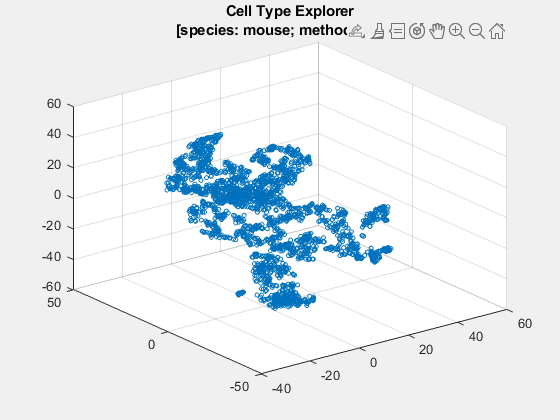

load example_data/celltypeexplorer_demo_data.mat
gui.sc_celltypeexplorer(X, genelist, s_tsne, "species", "mouse");

pause(3)

## Use the SCGEATOOL interactive tool

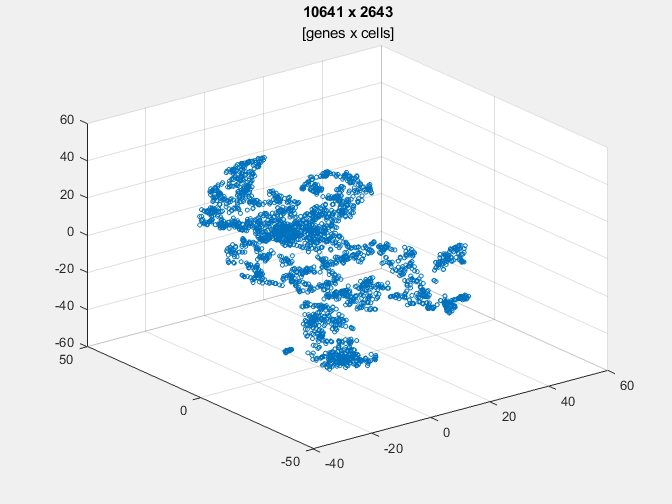

sce = SingleCellExperiment(X, genelist, s_tsne);
scgeatoolApp(sce)

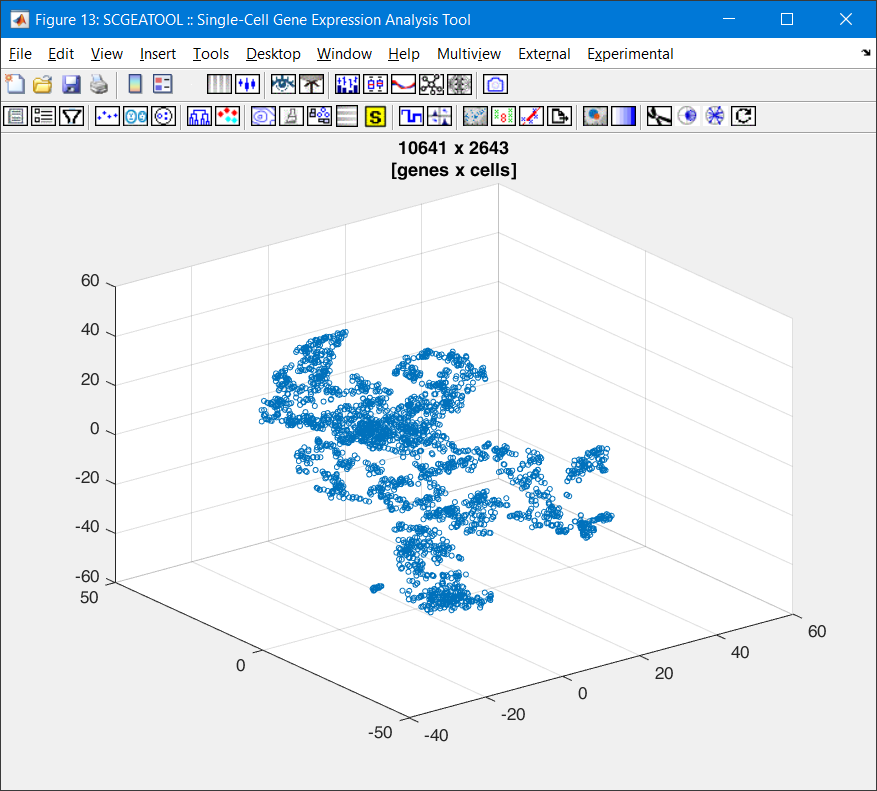

## The End